Multiple Maps

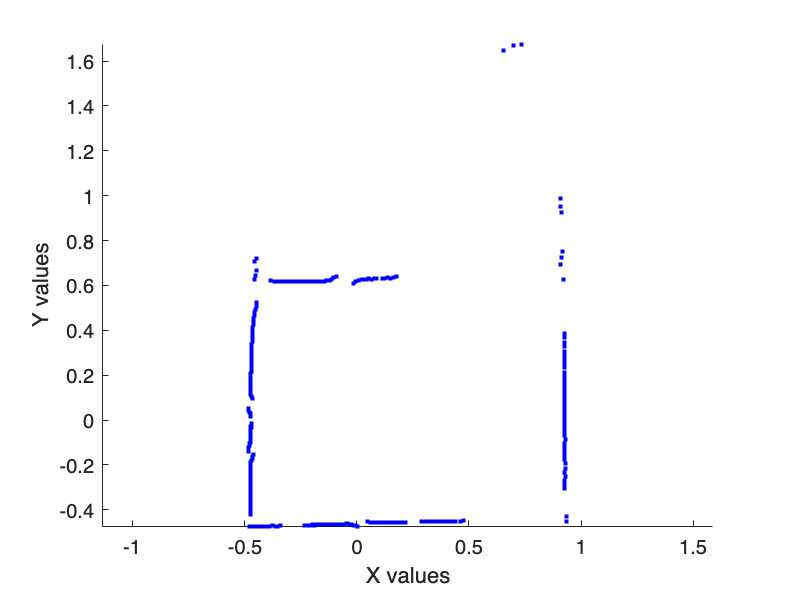

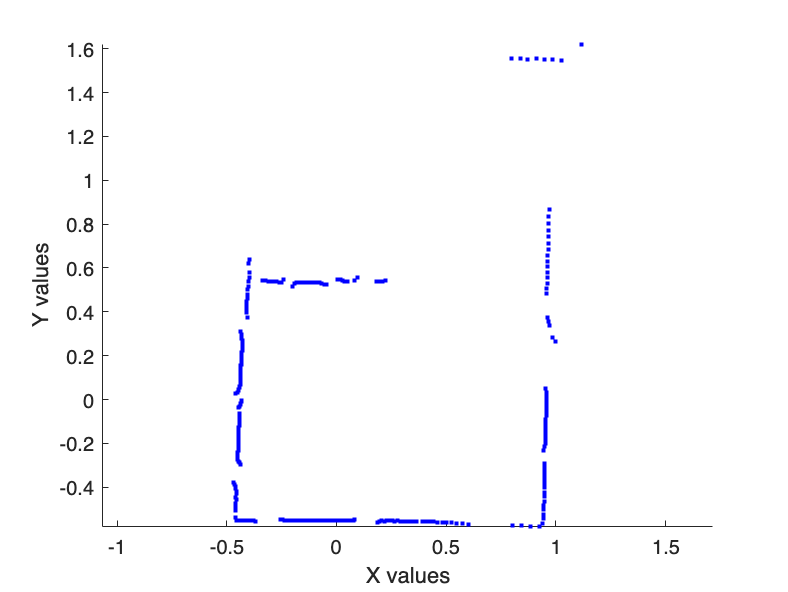

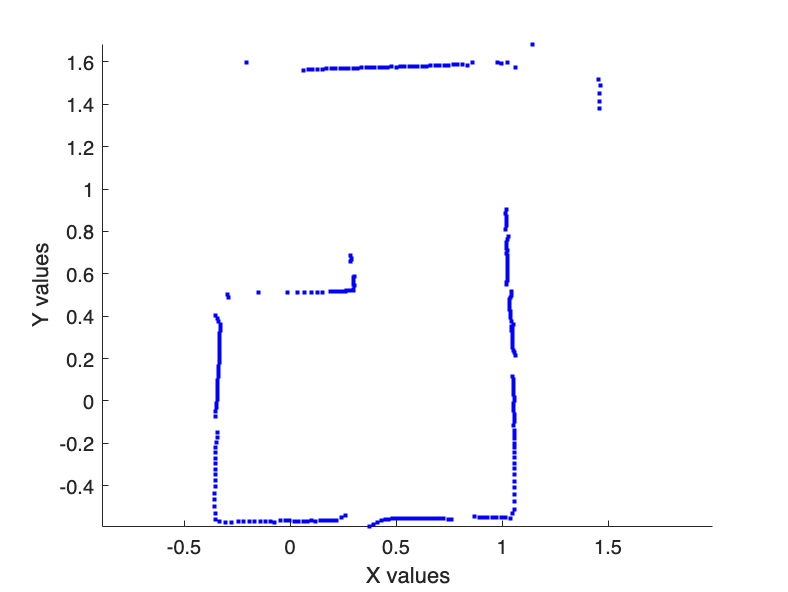

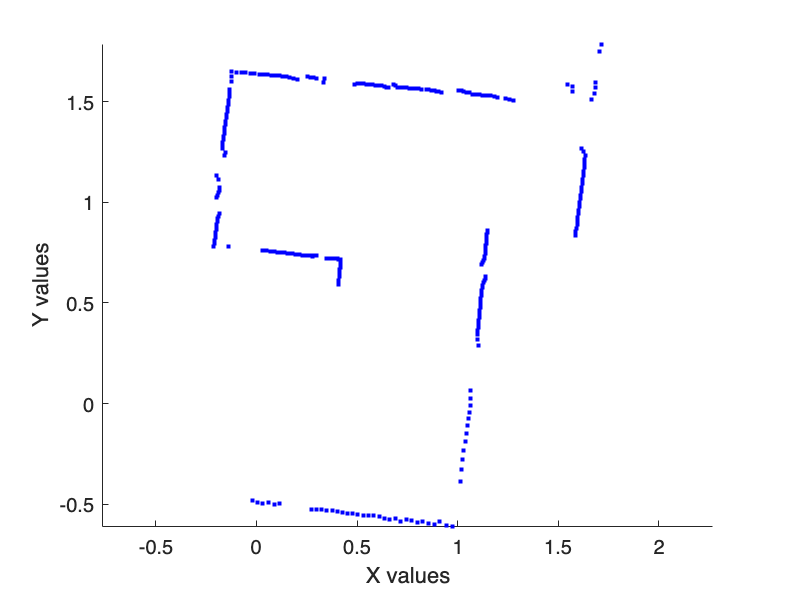

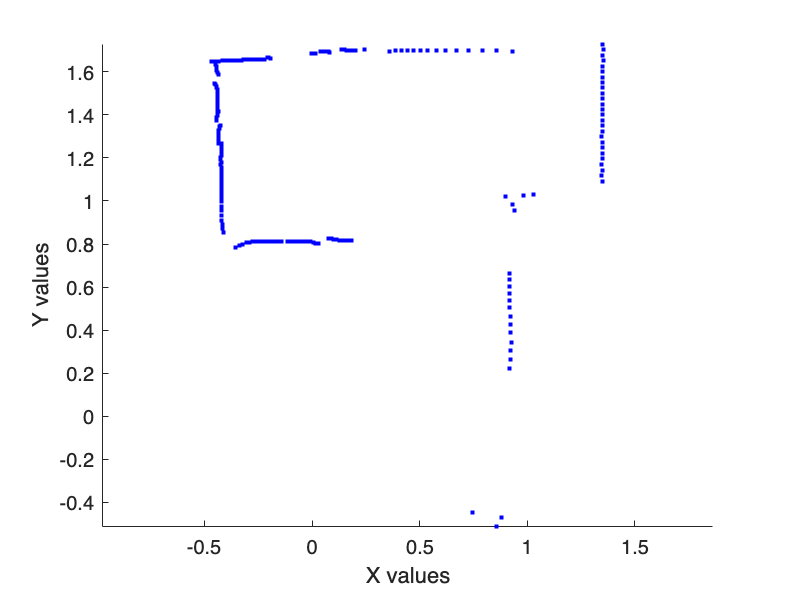

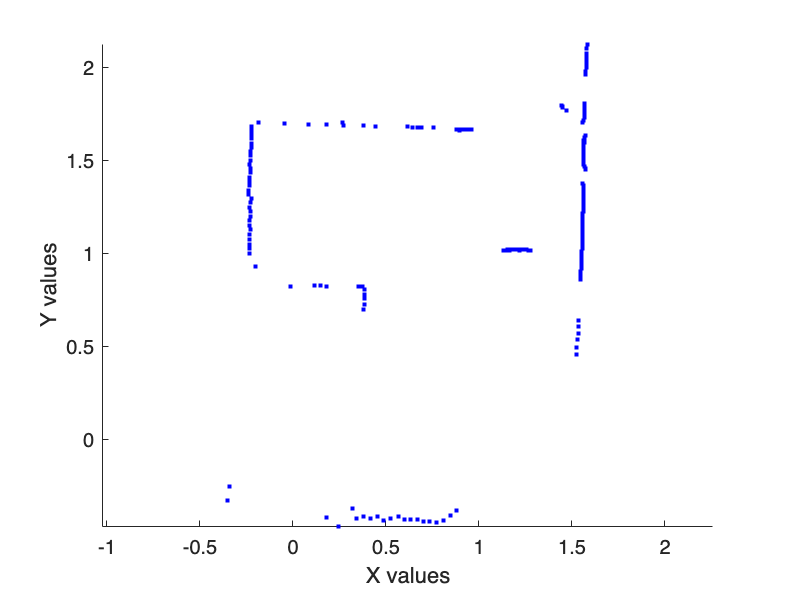

load('data_new.mat','angles','positions','scans');

combined_global_cleaned = [; ];

combined_plots = figure;
title('All the Plots');
for i=1:size(positions,1)
    theta = deg2rad(angles(i));
    ranges = scans{i}.ranges;
    thetas = scans{i}.thetasInRadians;
    robot_to_global = [cos(theta) -sin(theta) positions(i,1);
                     sin(theta) cos(theta) positions(i,2);
                     0 0 1];
    lidar_to_robot = [1 0 -0.08;
                      0 1 0;
                      0 0 1];
    lidar_to_global = robot_to_global * lidar_to_robot;
    matrix = [cos(thetas);
            sin(thetas)].*[ranges; ranges;];
    homogeneous_matrix = [matrix; ones(1, size(matrix,2))];
    cleaned = homogeneous_matrix(:, ranges~=0);
    global_cleaned = lidar_to_global*cleaned;
    figure;
    title("Position " + num2str(i))
    scatter(global_cleaned(1,:), global_cleaned(2,:), 'b.');
    axis("equal");
    xlabel("X values")
    ylabel("Y values")
    figure(combined_plots);
    hold on;
    scatter(global_cleaned(1,:), global_cleaned(2,:), 'b.');
    xlabel("X values")
    ylabel("Y values")
    axis("equal");

    combined_global_cleaned = [combined_global_cleaned, [global_cleaned(1, :); global_cleaned(2, :)]];
end

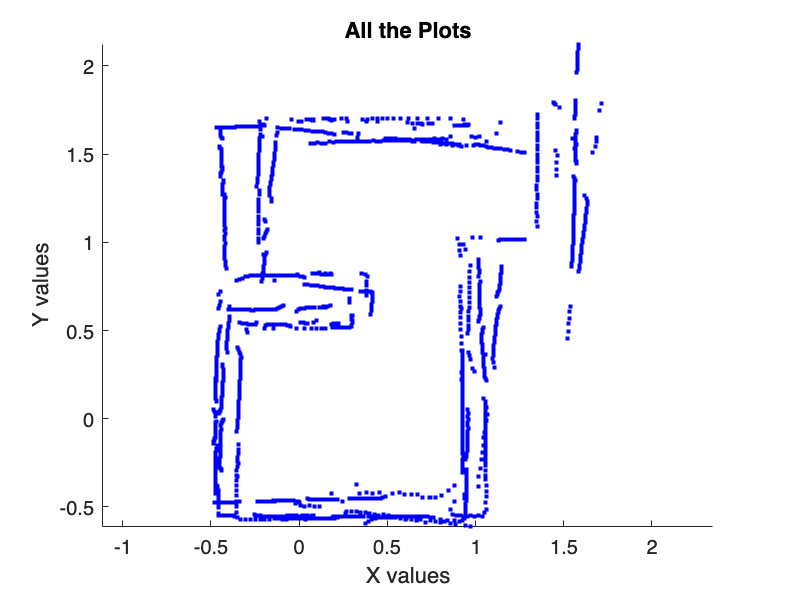

hold off;

Quiver and 3D plot

syms x y f;

point_x = combined_global_cleaned(1, :);
point_y = combined_global_cleaned(2, :);
[xvals, yvals]=meshgrid(-2:.2:2, -2:.2:2);

f = 0; % Quiver plot equation
for i = 1:25:size(point_x,2)
    current_x = point_x(i);
    current_y = point_y(i);
    % Add all walls to the quiver plot equation so it represents the map.
    f = f - (log(sqrt((x-current_x).^2 + (y-current_y).^2)));
end

% Add the ball to the equation.
f = f + (log(sqrt((x + 0).^2 + (y - 1.2).^2)))*35 % + 600.*(x - .2).^2 + 600.*(y - 1.2).^2

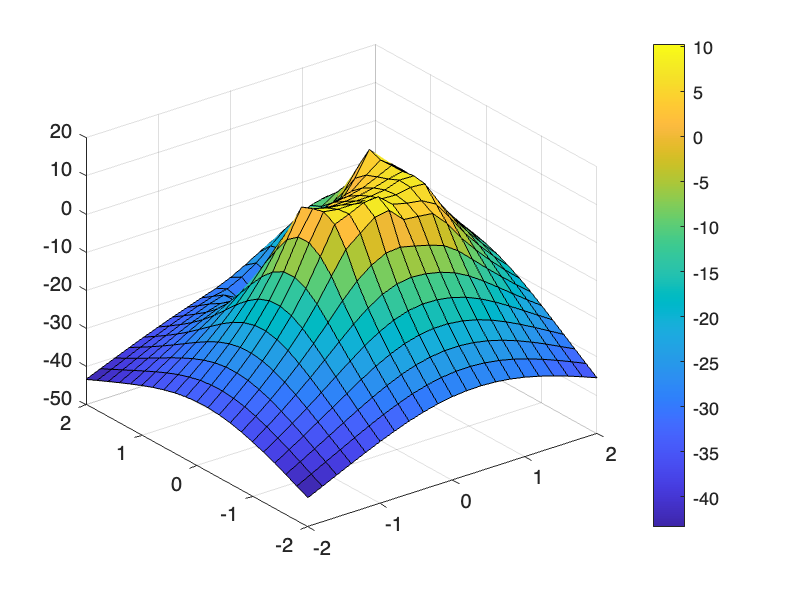

gradient_vector = gradient(f)

% Make all vectors the same length
grad_x = -.06 .* grad_x ./ sqrt(grad_x.^2 + grad_y.^2);
grad_y = -.06 .* grad_y ./ sqrt(grad_x.^2 + grad_y.^2);
quiver(x_grid, y_grid, grad_x, grad_y);
streamslice(x_grid, y_grid, grad_x, grad_y);

figure();
surf(xvals, yvals, double(subs(f, {x, y}, {xvals, yvals})));
colorbar;

Gradient Descent



% Equations
% f = 8*exp(-1.5*(x + y - 0.75).^2 - 0.5*(x - y - 0.75).^2) + 6*exp(-(x+0.75).^2-(y+0.25).^2);
gradient_vector = -1*gradient(f)


% Defining variables
lambda = 0.025;
tolerance = 0.09; % Defining how close we want to be to the top of the hill for ending the loop
wheel_base = 0.245;

% Numerival values for graphing contour lines
% [xvals, yvals] = meshgrid(linspace(-1.25, 1.25, 100), linspace(-0.5, 0.5, 100));
fvals = double(subs(f, {x, y}, {xvals, yvals}));

% Initial values for position and orientation of neato along with gradient
% at that point
position = [0.0; 0.0];
heading = [0; 0];
numerical_gradient = double(subs(gradient_vector, {x, y}, {position(1), position(2)}))

numerical_gradient = 1.0e+03 *

    0.2594
    1.4373


Connecting to the Neato.


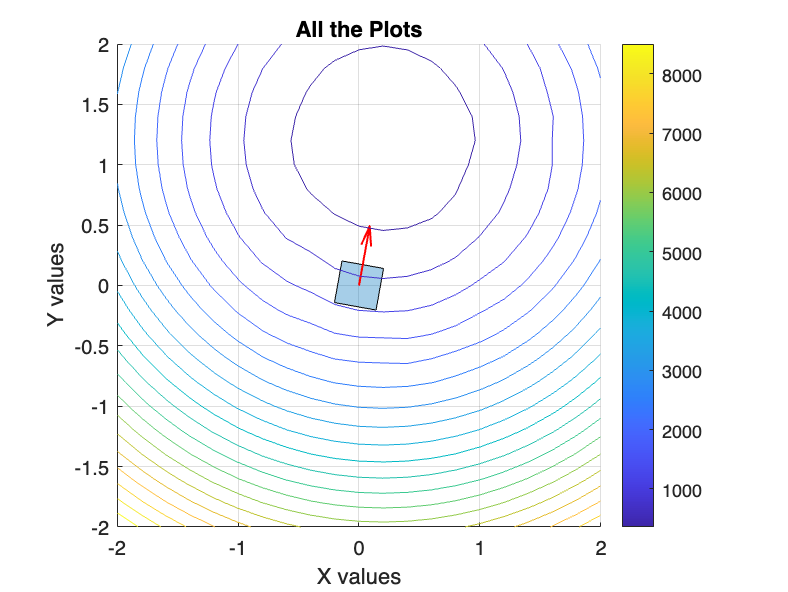


% Initializing the matrix to store positions and distances/angles in between them
positions = [position];
distances = [];
angles = [];

% Connecting the neato
useSim = true;

if useSim
    neatov2.connect();
    neatov2.setPositionAndOrientation(position(1), position(2), atan2(numerical_gradient(2), numerical_gradient(1)));
    neatov2.setFlatlandContours(xvals, yvals, fvals);
    neatov2.plotSim();
else
    neatov2.connect("192.168.16.73");
end

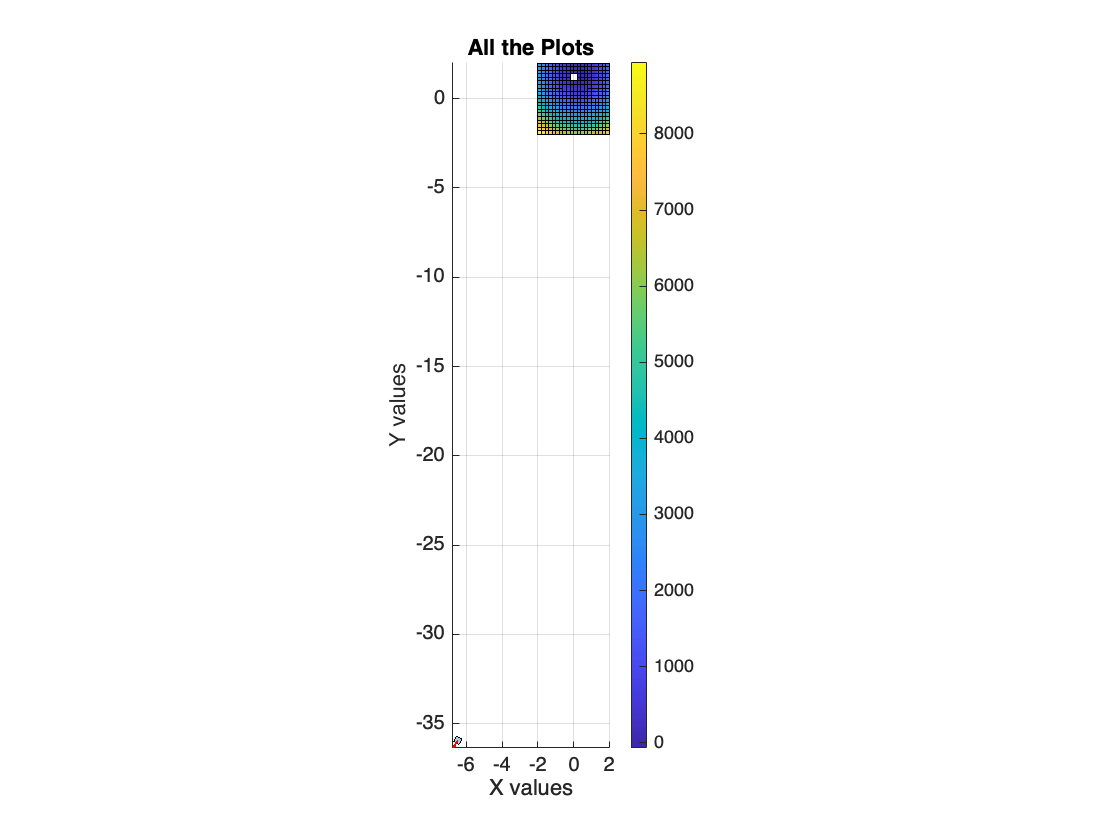


% Finding the path
while norm(numerical_gradient) > tolerance

    % Calculating the angle and the distance to be traveled by the neato
    angle = (atan2(numerical_gradient(2), numerical_gradient(1)) - atan2(heading(2), heading(1))) + pi;
    distance = lambda * norm(numerical_gradient) * -1;

    % Setting the wheel velocities
    if angle < 0
        v_left = 0.05;
        v_right = -0.05;
    else
        v_left = -0.05;
        v_right = 0.05;
    end

    % Rotation
    v_angular = (v_right - v_left)/wheel_base;
    duration = angle/v_angular;
    neatov2.driveFor(duration , v_left, v_right, useSim);

    % Forward
    v_left = 0.05;
    v_right = 0.05;
    v_linear = (v_left + v_right)/2;
    duration = distance/v_linear;
    neatov2.driveFor(duration , v_left, v_right, useSim);

    % Updating the position, orientation, and gradient
    position = position + lambda * numerical_gradient * -1;
    heading = numerical_gradient + pi;
    numerical_gradient = double(subs(gradient_vector, {x, y}, {position(1), position(2)}));

    if useSim
        % For the simulator only, you can set the position and orientation
        neatov2.setPositionAndOrientation(position(1), position(2), atan2(heading(2), heading(1)));

        % Plot the contour lines
        neatov2.setFlatlandContours(xvals, yvals, fvals);

        % For the simulator only, you can trigger a visualization of the
        % position and orientation of the Neato
        neatov2.plotSim();
    end

    % Storing the position, distance, angle
    positions = [positions, position];
    distances = [distances, distance];
    angles = [angles, angle];

end


% Plotting the path travelled by the neato
hold on;
plot(positions(1, :), positions(2, :));
hold off;
